# Diferenciación numérica

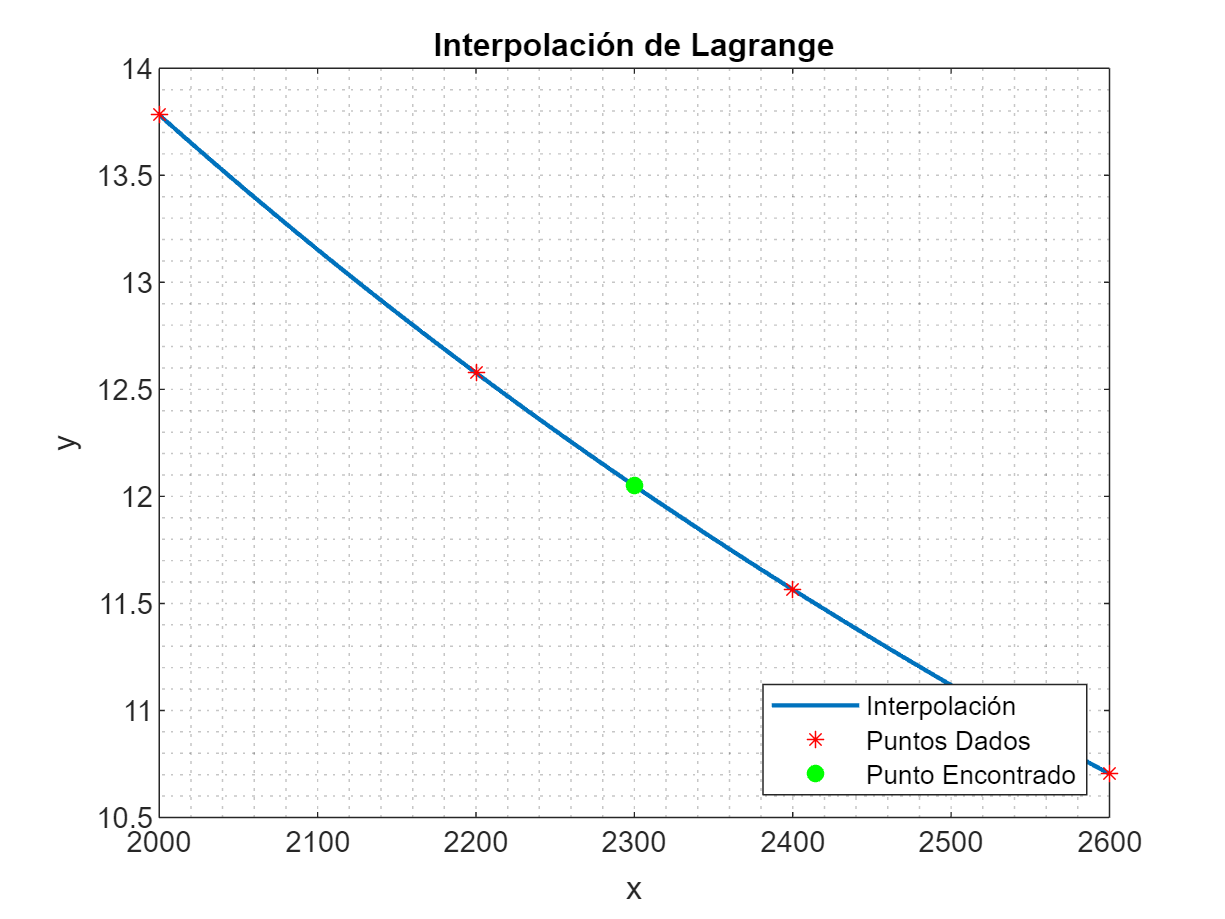

El polinomio, la primera, segunda y tercera derivada evaluadas en 2300son respectivamente: 


P_2300 =   12.049500000000002


dP_2300 =   -0.005051250000000


dP2_2300 =      4.300000000000001e-06


dP3_2300 =     -5.250000000000000e-09


format long
v=[2000 2200 2400 2600];
P=[13.782 12.577 11.565 10.704];
[P_2300,dP_2300,dP2_2300,dP3_2300]=diferenciacion_Lagrange(v,P,2300)

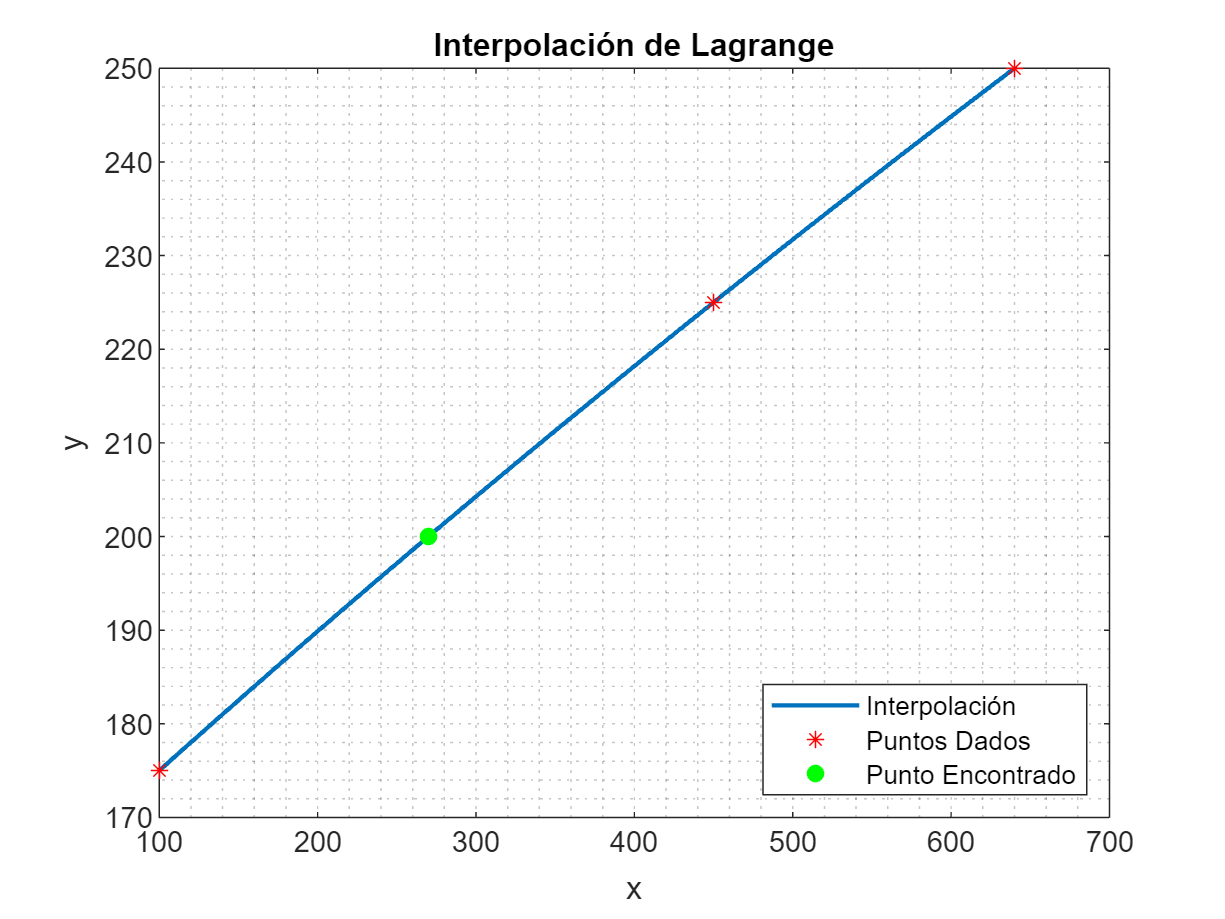

El polinomio, la primera, segunda y tercera derivada evaluadas en 270son respectivamente: 


P_270 =    200


dP_270 =    0.142887358831631


dP2_270 =     -4.681815827326663e-05


dP3_270 =      3.984524108363117e-08


P=[100 270 450 640 850];
T=[175 200 225 250 275];
[P_270,dP_270,dP2_270,dP3_270]=diferenciacion_Lagrange(P,T,270)

El polinomio, la primera, segunda y tercera derivada evaluadas en 270son respectivamente: 


P_270 = 200

dP_270 = 0.1429

dP2_270 = -4.6818e-05

dP3_270 = 3.9845e-08

P=[100 270 450 640];
T=[175 200 225 250];
[P_270,dP_270,dP2_270,dP3_270]=diferenciacion_Lagrange(P,T,270)

# Integración

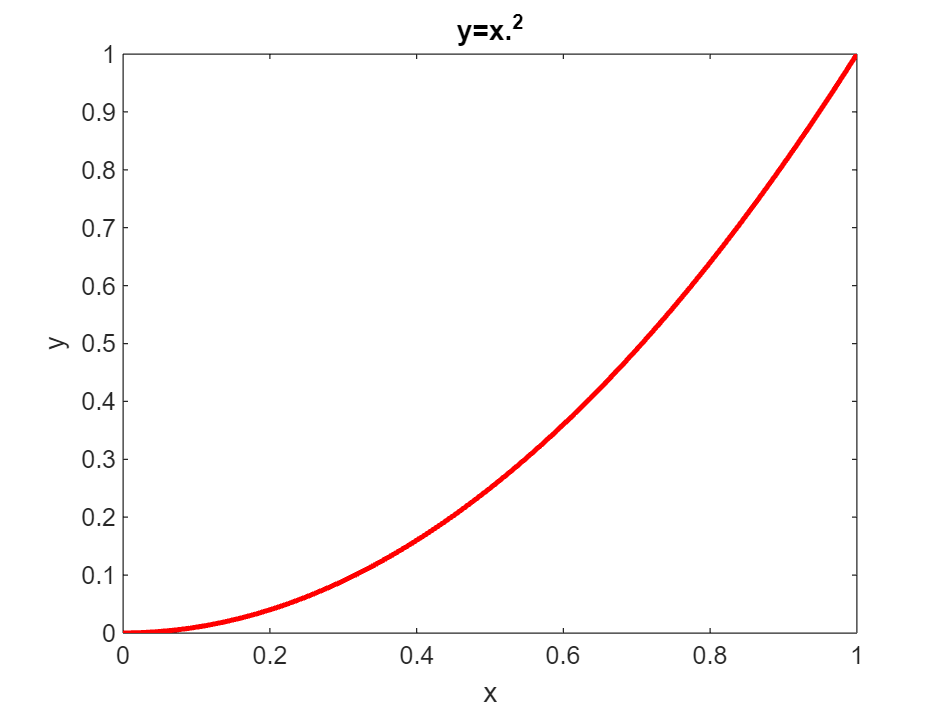

I =     6667/20000 


format rat
f=@(x)x.^2;
I=trapecio(f,0,1,100)

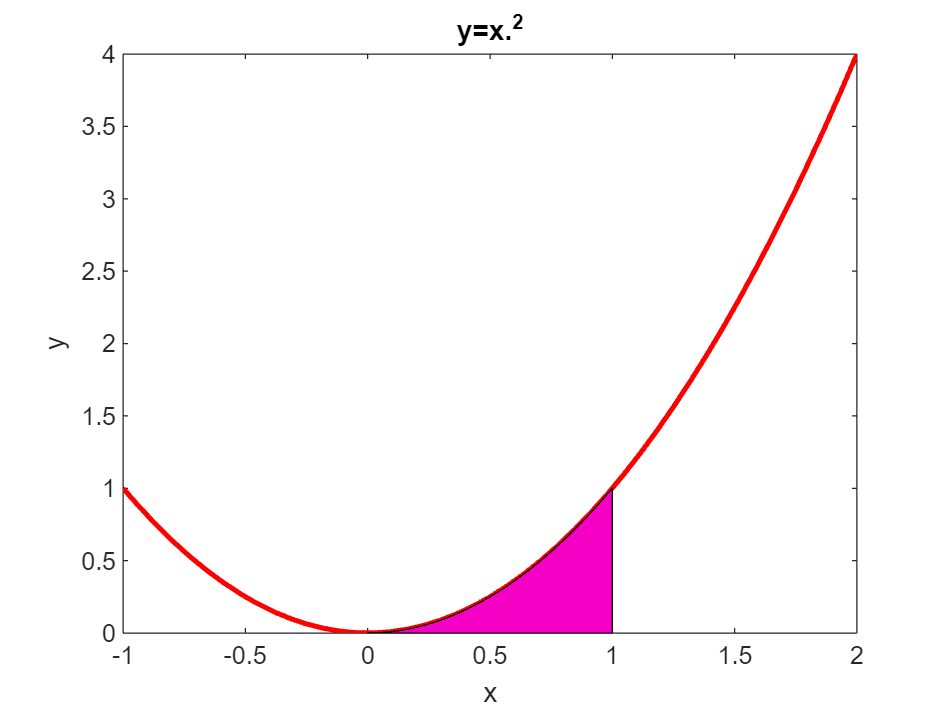

ans =        1/3     


Simpson(f,0,1,0.01)

I =    0.333350000000000


format long
I=trapecio2(f,0,1,0.01)

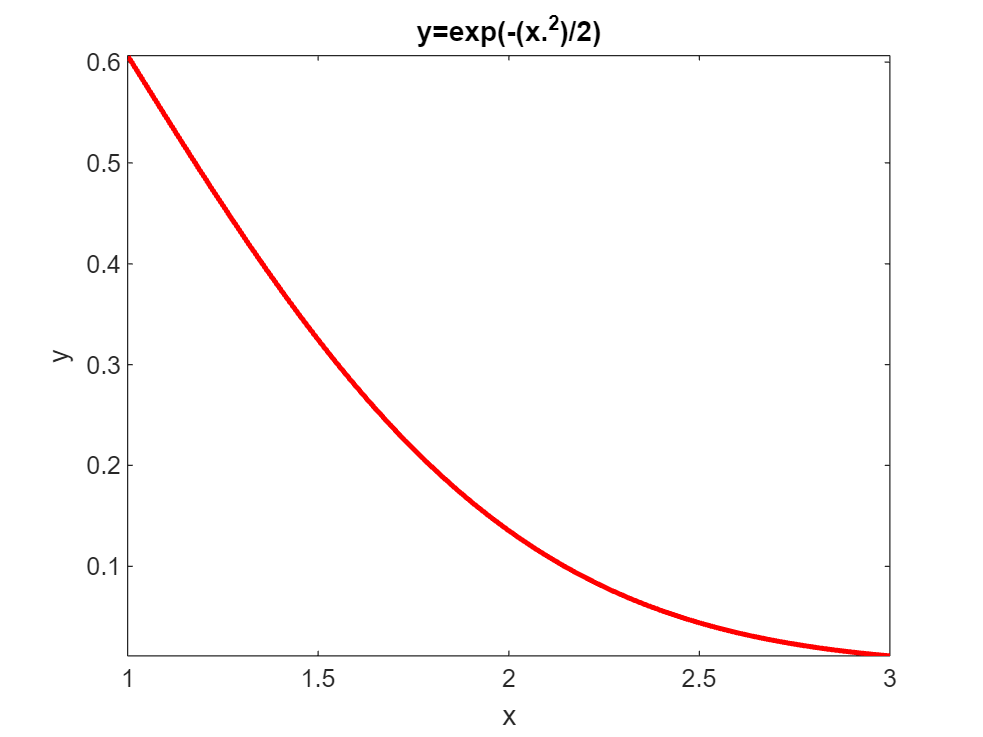

f=@(x)exp(-(x.^2)/2);
I=trapecio2(f,1,3,0.0001);

I=I/sqrt(2*pi)

I = 0.1573

.9987-.8413

ans = 0.1574

x=[-1 0 1 2 3 4];
y=[8 10 10 20 76 238];
I=trapecio3(x,y)

I = 239

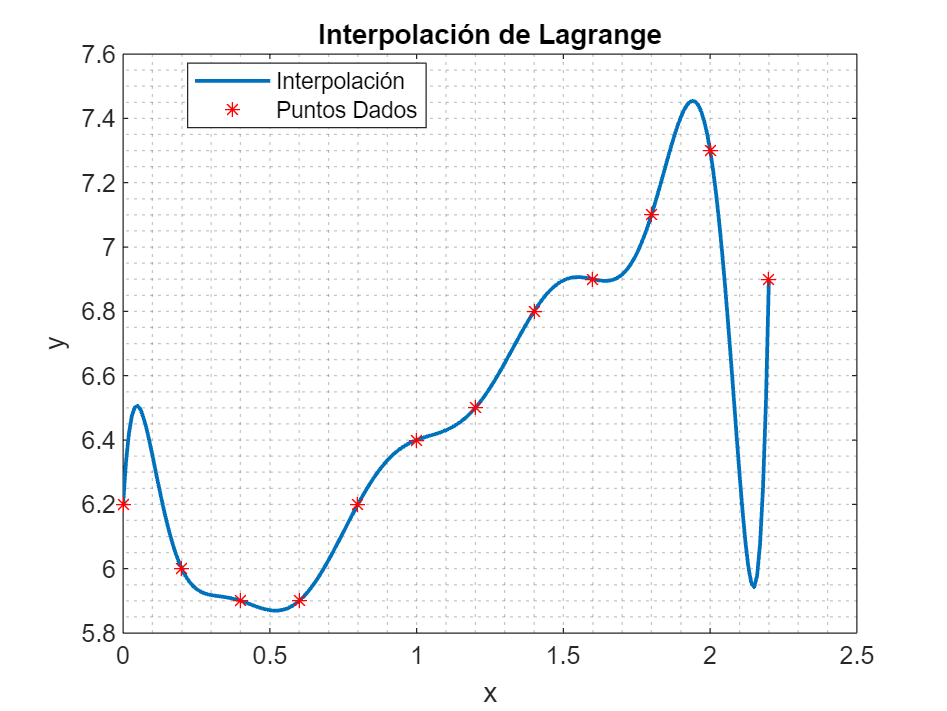

W = 14.3100

t=0:0.2:2.2;
G=[6.2 6 5.9 5.9 6.2 6.4 6.5 6.8 6.9 7.1 7.3 6.9];
W=trapecio3(t,G)

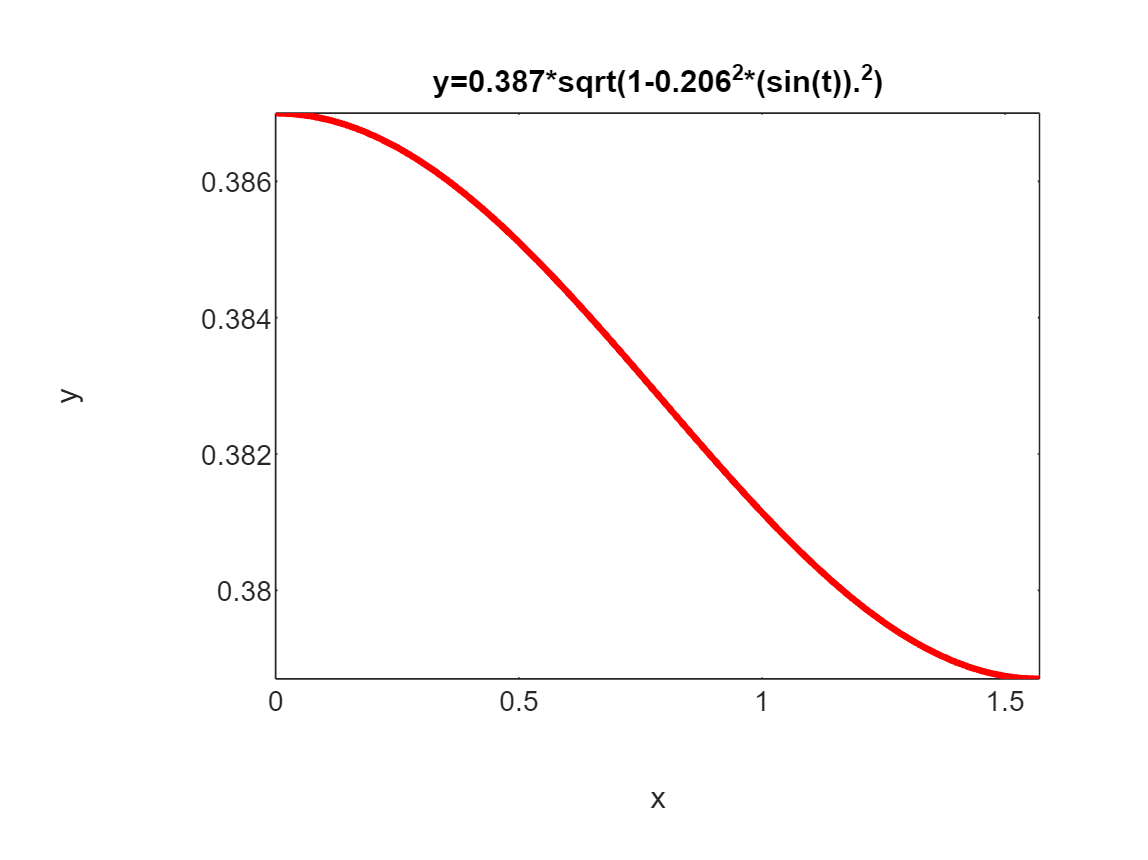

f=@(t)0.387*sqrt(1-0.206^2*(sin(t)).^2);
I=trapecio2(f,0,pi/2,0.01);

I=4*I

I = 2.4195

syms x
f1=cos(pi/2*cos(x))^2/sin(x)

$$f1 = \frac{{\cos\left(\frac{\pi \,\cos\left(x\right)}{2}\right)}^{2}}{\sin\left(x\right)}$$

limit(f1,x,pi)

$$ans = 0$$

limit(f1,x,0)

$$ans = 0$$

% f=@(x)cos(pi/2*cos(x)).^2./sin(x);
% I=trapecio2(f,0,pi,0.01)

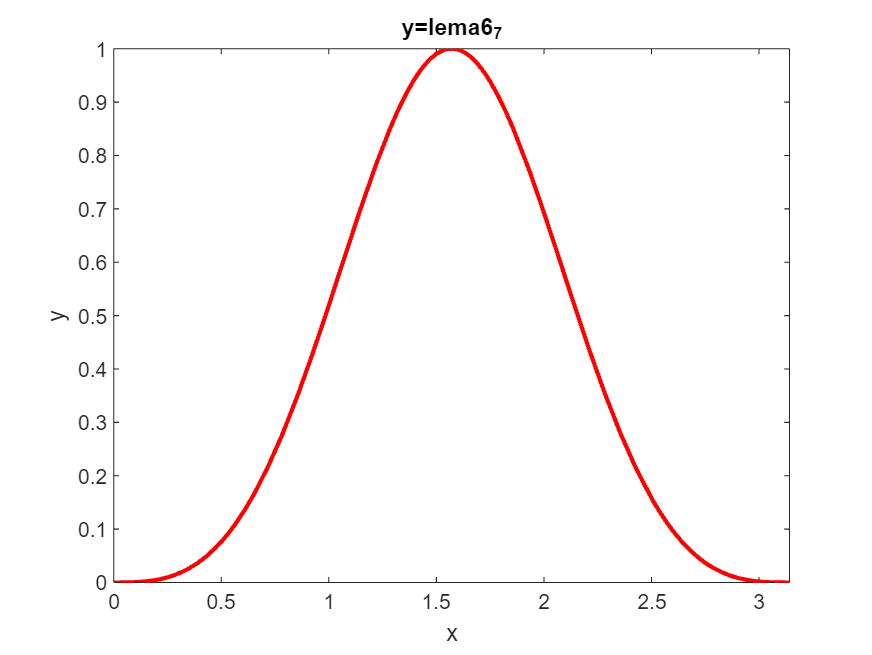

I = 1.2188

I=trapecio2(@problema6_7,0,pi,0.01)

f=@(x)cos(pi/2*cos(x)).^2./sin(x);
integral(f,0,pi)

Error using integral
Too many input arguments.

syms x y
f=sin(x)/x;
int(f)

$$ans = \mathrm{sinint}\left(x\right)$$

f=@(x)exp(-x.^2/2);
integral(f,-inf,2)

ans = 2.4496

## Gauss Legendre

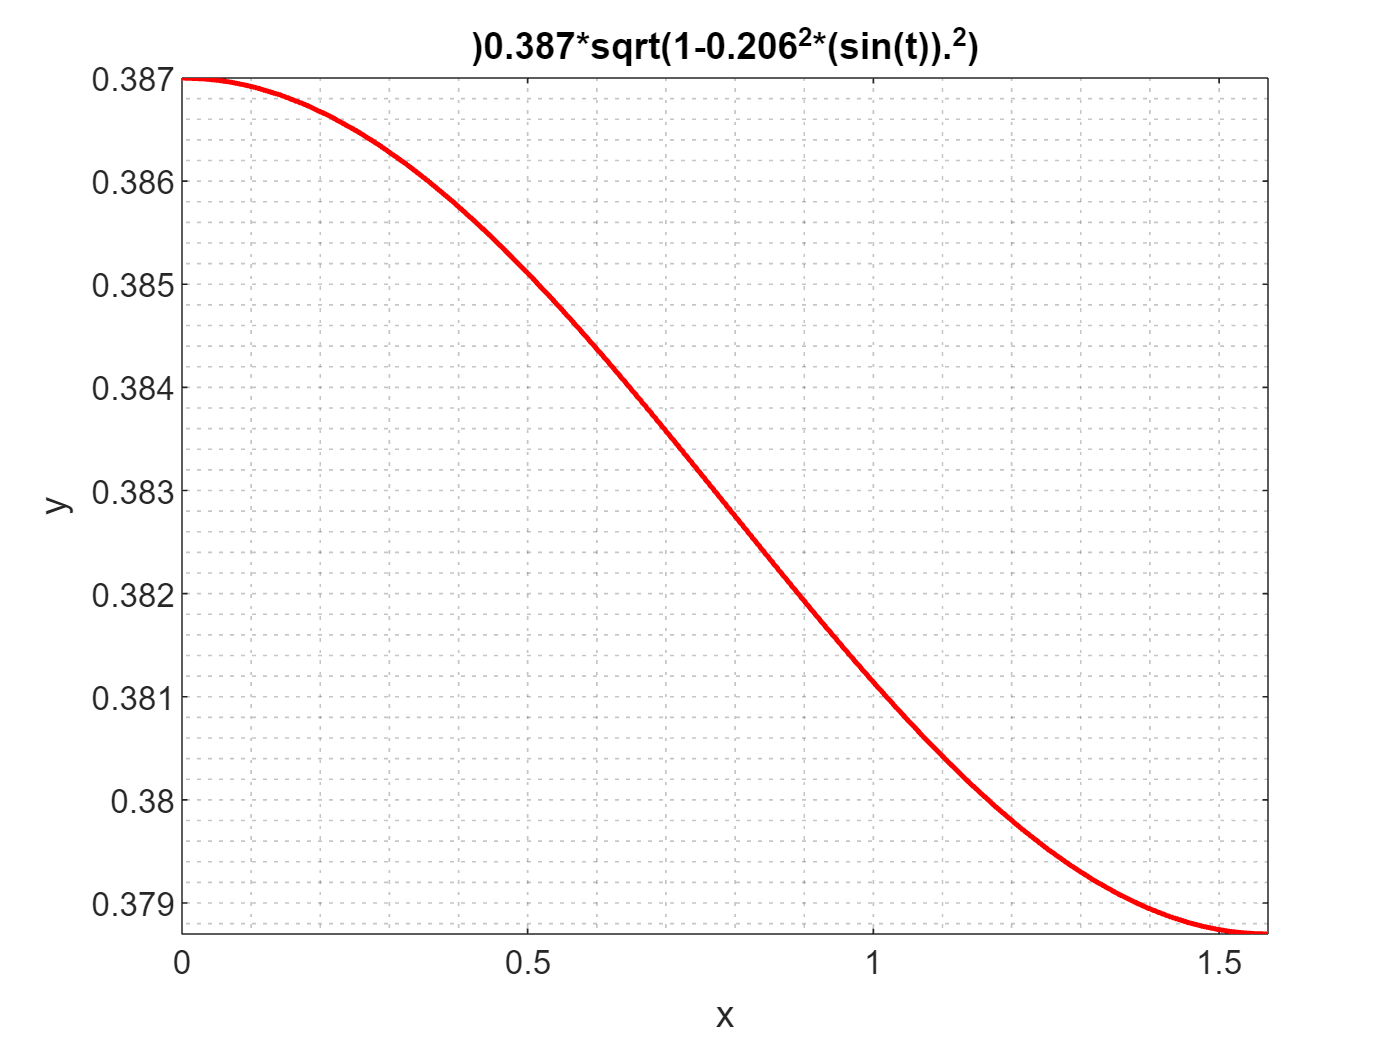

I = 0.6014

f=@(t)0.387*sqrt(1-0.206^2*(sin(t)).^2);
I=GaussLegendre(f,0,pi/2)

4*I

ans = 2.4056

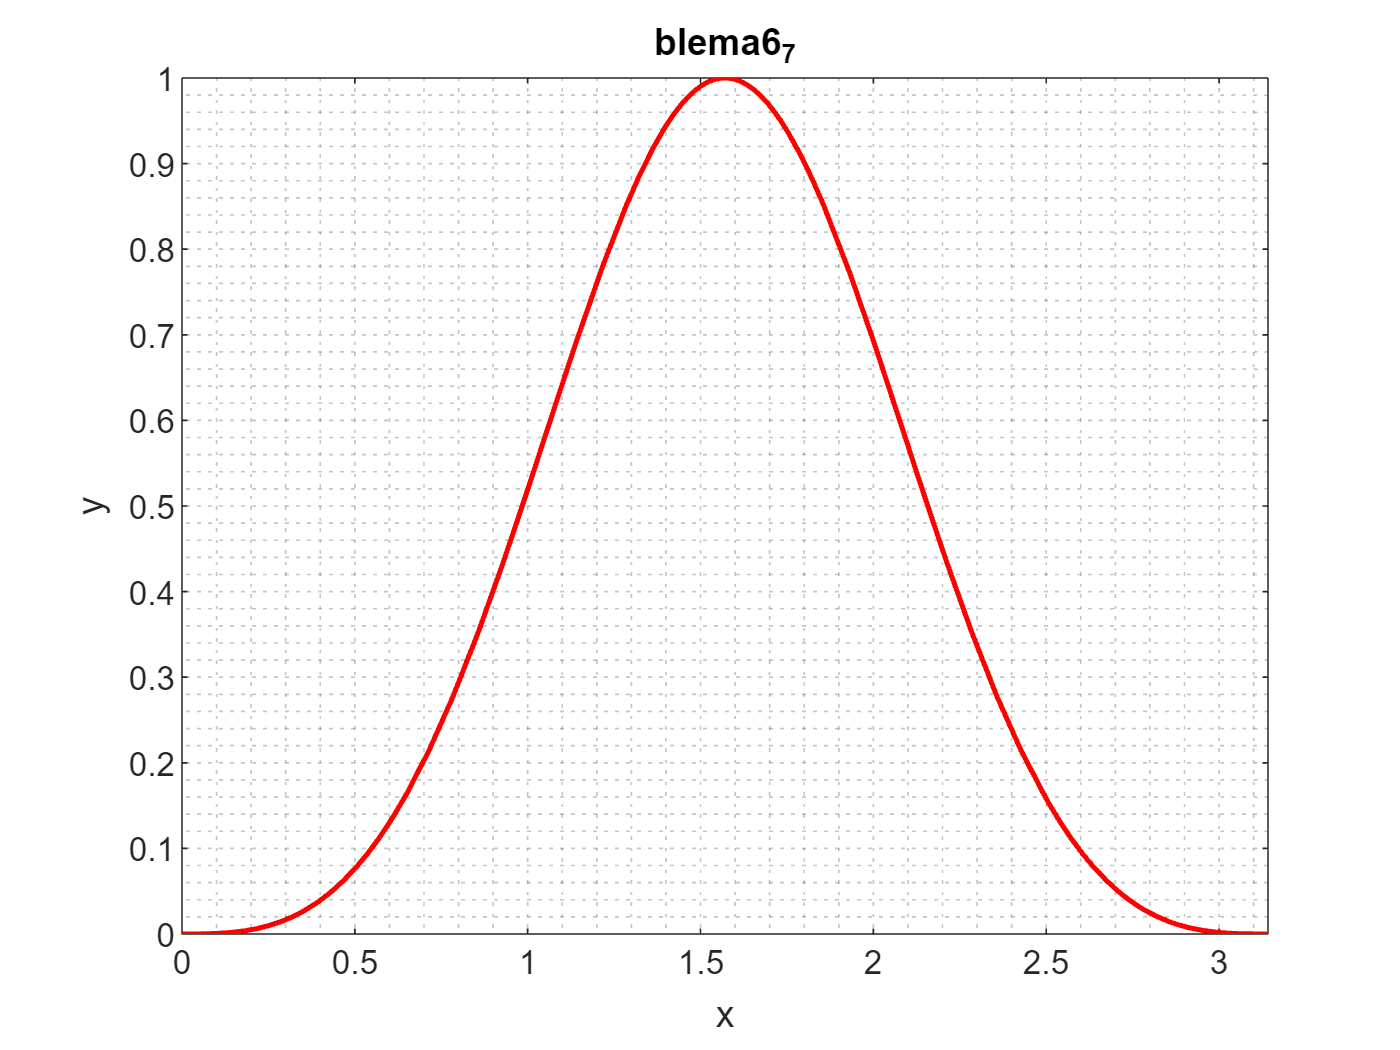

I = 1.2188

I=GaussLegendre(@problema6_7,0,pi)

x=[2 9 8 3];
y=[1 5 6 4];
[num,index]=sort(x)

num =      2     3     8     9


index =      1     4     3     2


y=y(index)

y =      1     4     6     5


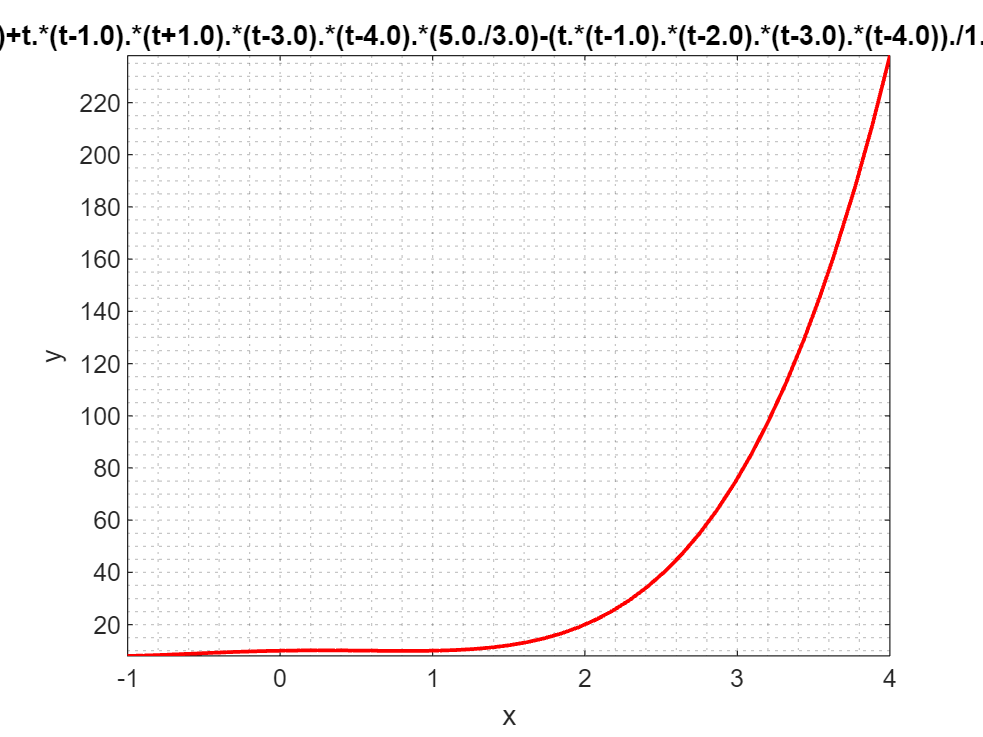

I = 219.1667

x=[-1 0 1 2 3 4];
y=[8 10 10 20 76 238];
I=GaussLegendreDiscreto(x,y)

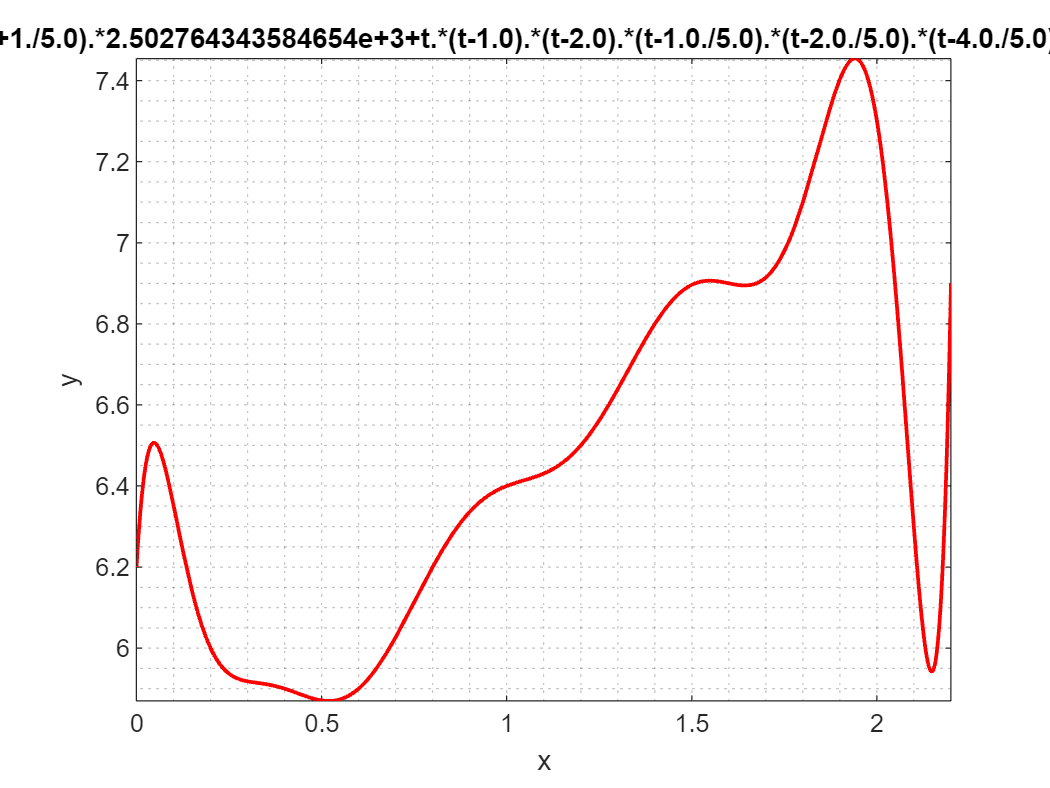

W = 14.2411

t=0:0.2:2.2;
G=[6.2 6 5.9 5.9 6.2 6.4 6.5 6.8 6.9 7.1 7.3 6.9];
W=GaussLegendreDiscreto(t,G)

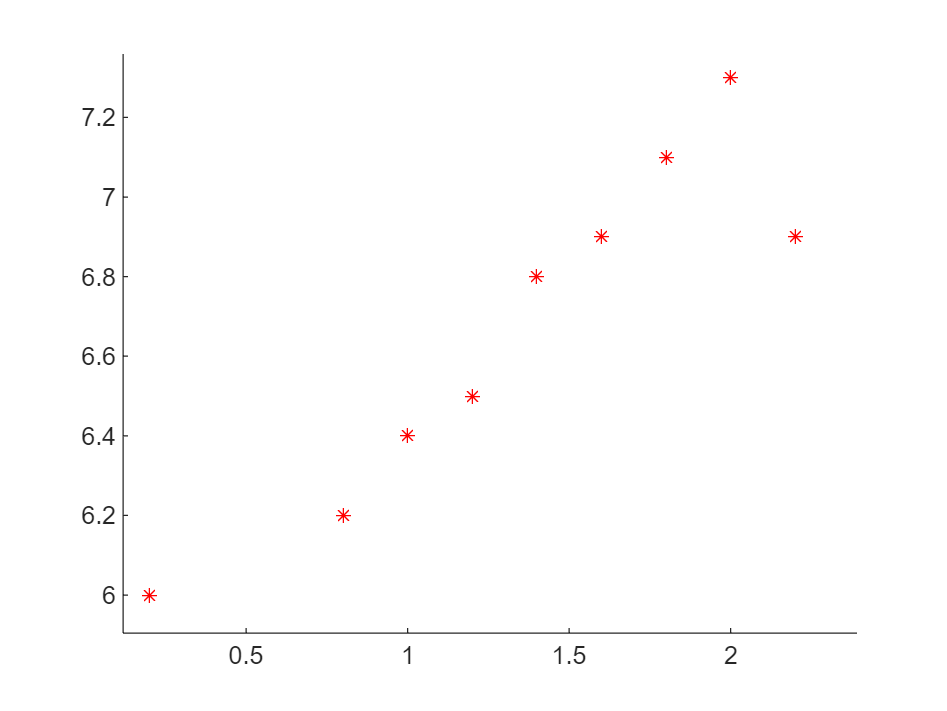

W = 14.2411

t=0:0.2:2.2;
G=[6.2 6 5.9 5.9 6.2 6.4 6.5 6.8 6.9 7.1 7.3 6.9];
W=GaussLegendreDiscreto2(t,G)

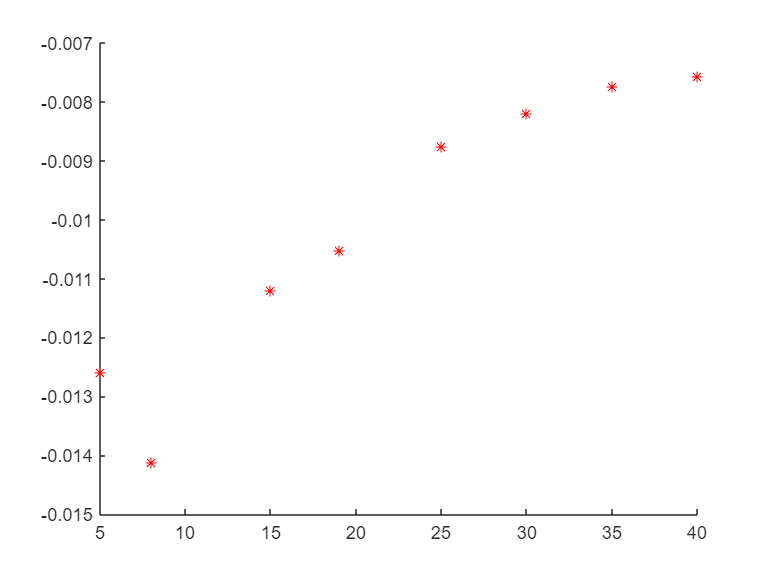

P=[5 8 15 19 25 30 35 40];
z=[0.937 0.887 0.832 0.8 0.781 0.754 0.729 0.697];
f=(z-1)./P;
ln_phi=GaussLegendreDiscreto2(P,f);

phi=exp(ln_phi)

phi = 0.7059

syms x y
f=8*x+exp(y);
a=0;
b=4;
g1=y;
g2=2*y;
var=[y x];
I=IntegralDobleSym(f,a,b,g1,g2,var)

I = 420.7945

clc; clear all;
f=@(x,y)8*x+exp(y);
a=0;
b=4;
g1=@(y)y;
g2=@(y)2*y;
IntegralDobleSum(f,a,b,g1,g2)

ki = 1.9603

si = 5.8809

I = 47.8898

ki = 0.0397

si = 0.1191

I = 47.8905

ki = 1.7967

si = 5.3900

I = 131.9404

ki = 0.2033

si = 0.6100

I = 131.9888

ki = 1.5255

si = 4.5766

I = 168.1801

ki = 0.4745

si = 1.4234

I = 168.6856

ki = 1.1834

si = 3.5503

I = 178.3685

ki = 0.8166

si = 2.4497

I = 180.8430

ans = 361.6860

syms x y z
f=x^2;
xlim=[0 1];
ylim=[0 1];
zlim=[0 1];
var=[x y z];
I=IntegralTripleSym(f,xlim,ylim,zlim,var)

I = 0.3333

f=y*exp(-x*y);
xlim=[0 1];
ylim=[0 1];
zlim=[0 1];
var=[x y z];
I=IntegralTripleSym(f,xlim,ylim,zlim,var)

I = 0.3679


$$\int_0^\pi\int_0^{\pi/4}\int_0^{\sec\phi}\sin{2\phi}\thinspace d\rho \thinspace d\phi \thinspace d\theta = 2\pi\left(-\frac{1}{\sqrt{2}}+1\right)$$


f=sin(2*y);
xlim=[0 sec(y)];
ylim=[0 pi/4];
zlim=[0 pi];
var=[x y z];
I=IntegralTripleSym(f,xlim,ylim,zlim,var)

I = 1.8403

2*pi*(-1/sqrt(2)+1)

ans = 1.8403

syms x y
f=x+2*y;
IntegralDobleSym(f,-1,1,2*x^2,1+x^2,[x y])

ans = 2.1333

32/15

ans = 2.1333

f=x^2+y^2;
IntegralDobleSym(f,0,4,y/2,sqrt(y),[y x])

ans = 6.1714

216/35

ans = 6.1714

syms x y z
f=x;
IntegralTripleSym2(f,0,2,0,sqrt(z),0,sqrt(z-y^2),[z y x])

ans =    0.754243630834812


8*sqrt(2)/15

ans =    0.754247233265651


f=@(t,y)[2*y(1)+4*y(2) -y(1)+6*y(2)]

f = function_handle with value:
    @(t,y)[2*y(1)+4*y(2),-y(1)+6*y(2)]


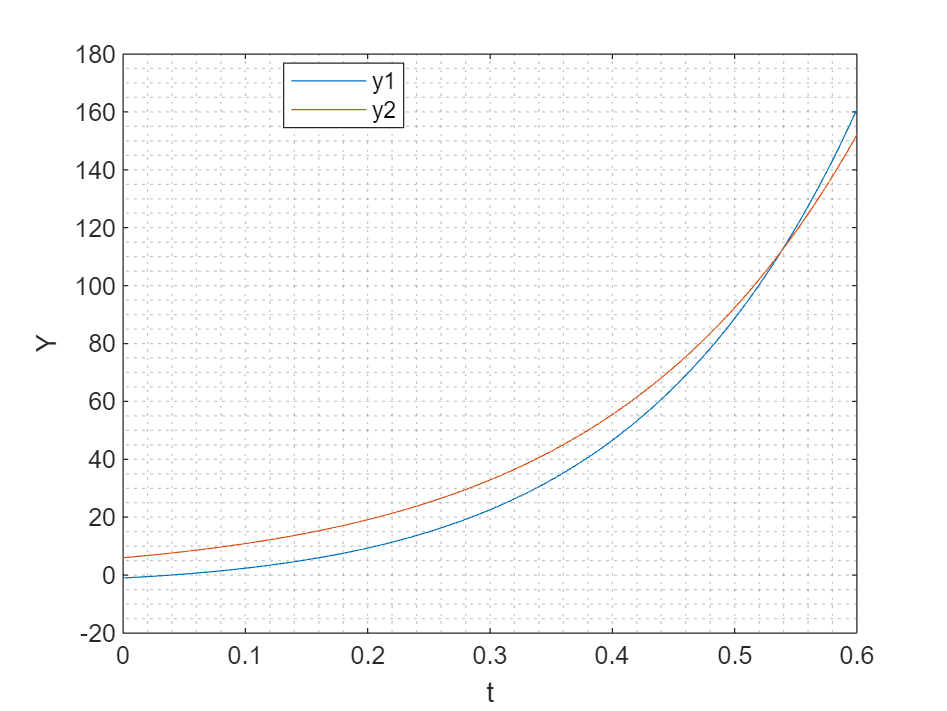

A = 601×3 table
      t         y1         y2  
    _____    ________    ______

        0          -1         6
    0.001     -0.9779    6.0371
    0.002    -0.95561    6.0744
    0.003    -0.93313    6.1119
    0.004    -0.91045    6.1496
    0.005    -0.88758    6.1875
    0.006     -0.8645    6.2256
    0.007    -0.84123     6.264
    0.008    -0.81775    6.3025
    0.009    -0.79408    6.3412
     0.01     -0.7702    6.3802
    0.011    -0.74612    6.4193
    0.012    -0.72183    6.4587
    0.013    -0.69733    6.4983
    0.014    -0.67263    6.5381
    0.015    -0.64772    6.5781


Y0=[-1 6];

A=RungeKuttaO4(f,Y0,0,0.6,0.001);

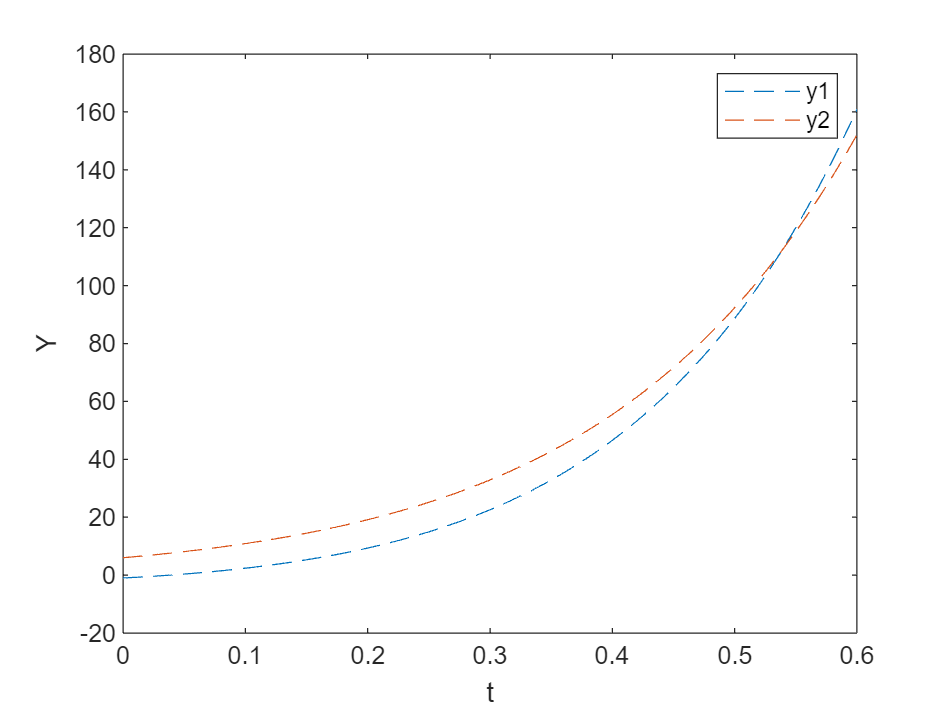

A = 601×3 table
      t         y1         y2  
    _____    ________    ______

        0          -1         6
    0.001     -0.9779    6.0371
    0.002    -0.95561    6.0744
    0.003    -0.93313    6.1119
    0.004    -0.91045    6.1496
    0.005    -0.88758    6.1875
    0.006     -0.8645    6.2256
    0.007    -0.84123     6.264
    0.008    -0.81775    6.3025
    0.009    -0.79408    6.3412
     0.01     -0.7702    6.3802
    0.011    -0.74612    6.4193
    0.012    -0.72183    6.4587
    0.013    -0.69733    6.4983
    0.014    -0.67263    6.5381
    0.015    -0.64772    6.5781


v={'t','y1','y2'};
A=RungeKuttaO4_2(f,Y0,0,0.6,0.001,v)

%t vs y1,y2,y3

f=@(t,y)[y(2); 75*sin(5*t)-20*y(2)-166.6666*y(1)];
v={'t','Q'}

v = 1×2 cell array
    {'t'}    {'Q'}


Y0=[0 0]

Y0 =      0     0


A=RungeKuttaO4_2(@Problema7_5Nieves,Y0,0,2,0.001,v)

Error: File: Problema7_5Nieves.mlx Line: 8 Column: 12
Local function name must be different from the script name.

Error in RungeKuttaO4_2 (line 8)
    G1=h*f(t(i),Y(i,:));


f=@(x)x;
a=0;
b=1;
I=integral(f,a,b)

Error using integral
Too many input arguments.

f=@(x)cos(pi/2*cos(x)).^2./sin(x);
integral(f,0,pi)

Error using integral
Too many input arguments.

xmin = 0;
xmax = 1;
ymin = 0;
ymax = @(x) x.^3;
fun= @(x,y)x;
fun2= @(x,y)y;
xbar = quad2d(fun,xmin,xmax,ymin,ymax);
fprintf('xbar = %f\n',xbar);

xbar = 0.200000


ybar = integral2(fun2,xmin,xmax,ymin,ymax);
fprintf('ybar = %f\n',ybar);

ybar = 0.071429



f="12"

f = "12"

str2sym(f)

$$ans = 12$$